# MATLABによる予知保全・データ解析の例

## はじめに

IoT (Internet of Things) とビッグデータの利用拡大にともない、さまざまな分野で予知保全 (PdM: Predictive Maintenance) の重要性が高まっています。なかでも、膨大な時系列データの中から異常状態を検出することは、例えば装置故障の予兆を事前に察知することにもつながるため重要です。さまざまな異常検出の手法を、以下の表に示します。

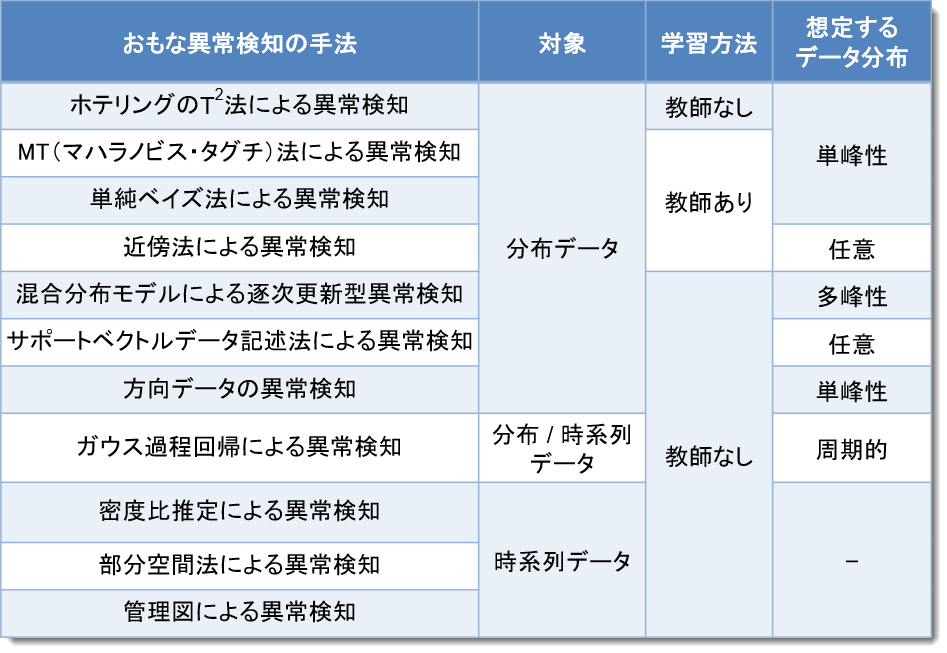

これら各種手法のなかでも、多次元データの中から「教師なし」で異常を検出する手法は、あまり異常が発生しないケースに適用可能であることから、実用上とても重要な手法といえます。そこで本デモでは、「教師無し」で異常を検出する以下の3つの手法を具体例とともに紹介します。

- ホテリングの$T^2$法 (Htelling's T-square method) 

- 混合分布モデルによる異常検出

- 1-Class SVMによる異常検出

より現実に即したデモとするため、以下では C-MAPSST (Commercial Modular Aero-Propulsion SystemSimulation) によるターボファンエンジン (Turbofan engine) のセンサーデータセット [1, 2] を使用します。このデータセットには、多数のターボファンエンジン (航空機用エンジンの一種) について、メンテナンス直後から故障が発生するまでの間に得られた各種センサーデータが含まれています。

データセットには、あらかじめ交差検証用に学習用と検証用のデータが含まれています。学習用には、メンテナンス直後から障害発生までのデータが含まれます。一方、検証用には、学習用とは別のエンジン群の、メンテナンス直後から障害発生の直前までのデータが含まれています。具体的には以下のとおりです。

データセット: FD001

- 学習用: 100台分

- 検証用: 100台分

- 障害: HPC劣化

[1] A. Saxena, K. Goebel, D. Simon and N. Eklund, "Damage Propagation Modeling for Aircraft Engine Run-to-Failure Simulation," International Conference on Prognostics and Health Management, (2008).

[2] [Turbofan Engine Degradation Simulation Data Set](https://ti.arc.nasa.gov/tech/dash/pcoe/prognostic-data-repository/#turbofan)

## データセットの読み込み

データセットFD001を読み込みます。

dataTrain = importFDdata('train_FD001.txt');
dataTest = importFDdata('test_FD001.txt');
RULTest = csvread('RUL_FD001.txt');

## データの前処理

学習用データに対して、前処理をおこないます。具体的には、以下の3つの処理をおこないます。

- 変数名の設定

- 有用なセンサーデータの抽出

- 残存耐用時間 (RUL: Remaining Useful Life) に基づく4段階のラベル付け

最後の「4段階のラベル付け」は、以下のように想定しました。

- RUL = 0~50サイクル : **urgent**

- RUL = 51~125 cycles : **short**

- RUL = 126~200 cycles: **medium**

- RUL = 201~ : **long**

dataTrain = dataCleaning(dataTrain);
head(dataTrain)

ans = 8×17 table
    Unit    Time    LPCOutletTemp    HPCOutletTemp    LPTOutletTemp    TotalHPCOutletPres    PhysFanSpeed    PhysCoreSpeed    StaticHPCOutletPres    FuelFlowRatio    CorrFanSpeed    CorrCoreSpeed    BypassRatio    BleedEnthalpy    HPTCoolantBleed    LPTCoolantBleed    Label 
    ____    ____    _____________    _____________    _____________    __________________    ____________    _____________    ___________________    _____________    ____________    _____________    ___________    _____________    _______________    _______________    ______

     1      -191       641.82           1589.7           1400.6              554.36             2388.1          9046.2               47.47              521.66             2388          8138.6          8.4195            392              39.06             23.419         medium
     1      -190       642.15           1591.8           1403.1              553.75               2388          9044.1               47.49              52

同様に、検証用データに対しても前処理を施します。

% 同様の前処理を検証用データに適用
dataTest = dataCleaning(dataTest);

% 各エンジンの、障害発生直前のデータを除去
dataTest = dataTest(dataTest.Time == 0, 1:end-1);
dataTest.Time = -RULTest;

% RULに基づき4段階のラベル付け
catname = {'urgent','short','medium','long'};
dataTest.Label = discretize(-dataTest.Time, [0 51 126 201 inf],'categorical',catname);

% 一部を表示
head(dataTest)

ans = 8×17 table
    Unit    Time    LPCOutletTemp    HPCOutletTemp    LPTOutletTemp    TotalHPCOutletPres    PhysFanSpeed    PhysCoreSpeed    StaticHPCOutletPres    FuelFlowRatio    CorrFanSpeed    CorrCoreSpeed    BypassRatio    BleedEnthalpy    HPTCoolantBleed    LPTCoolantBleed    Label
    ____    ____    _____________    _____________    _____________    __________________    ____________    _____________    ___________________    _____________    ____________    _____________    ___________    _____________    _______________    _______________    _____

     1      -112       642.58           1581.2           1398.9              554.42             2388.1          9056.4               47.23              521.79           2388.1          8130.1          8.4024            393              38.81             23.355         short
     2       -98       642.55           1586.6           1410.8              553.52             2388.1          9044.8               47.67              521.7

## データの可視化

確認のため、データ全体を可視化します。

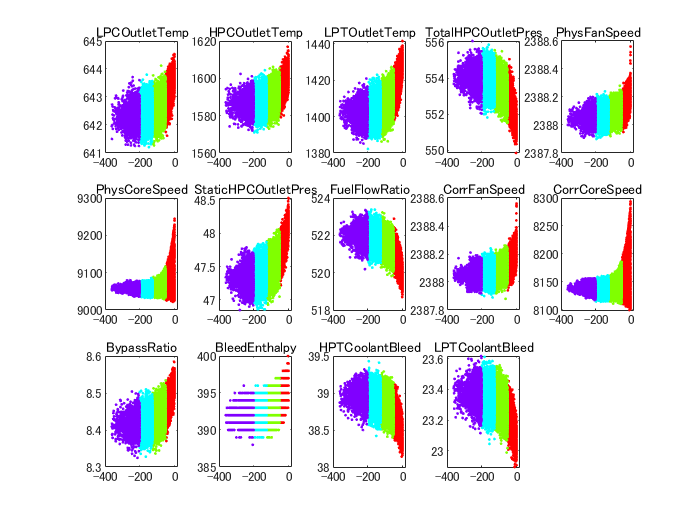

% 学習データの可視化 (4種類のラベル long/medium/short/urgent 毎に色分けして表示) 
figure
for kk = 1:14
    subplot(3,5,kk);
    gscatter(dataTrain.Time, dataTrain{:,2+kk}, dataTrain.Label);
    title(dataTrain.Properties.VariableNames{2+kk})
    legend('off');
end

## 各センサーデータを標準化

各センサーデータを、平均 = 0、分散 = 1 となるようスケーリング (Z-スコア化) します。

dataTrainZ = dataTrain;
[dataTrainZ{:,3:end-1}, mu, sigma] = zscore(dataTrainZ{:,3:end-1});

## 主成分分析による次元削減

データには14種類のセンサーデータが含まれています。つまり、各データ点は14次元空間内での点と考えることができます。このままではデータ全体の分布を確認できないため、まずは主成分分析 (PCA: Principal Component Analysis) を適用して次元削減を試みます。今回のデータでは、以下に示すように第1主成分と第2主成分のみでデータ全体の約 79% の情報が含まれることが確認できます。このため、第1主成分 - 第2主成分平面上にデータをプロットすることで、14次元空間内での全体的なデータの分布を確認することができると考えられます。

実際に第1主成分 - 第2主成分平面上にデータをプロットして、4種類のラベルで点の色を変えると、以下の図のようになります。こうしてデータ全体の傾向を見ることで、おおよそ以下のことが見て取れます。

- 'long' クラスのデータは3個のクラスタを形成している

- とりわけ第1主成分の値が4種類のラベルと有意に関連している

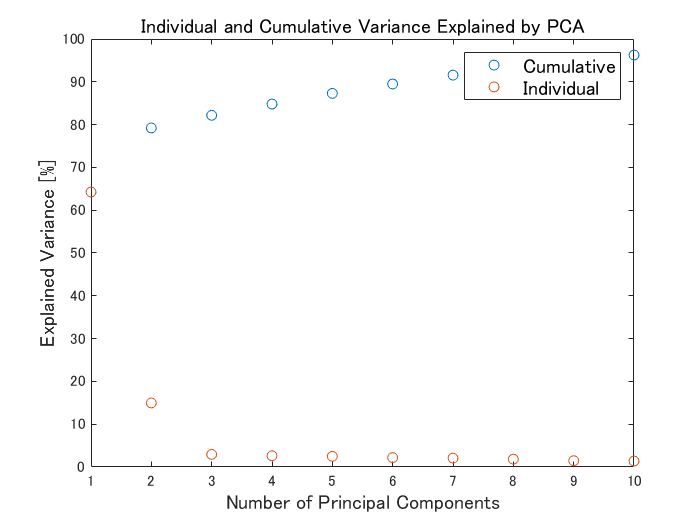

varName = dataTrainZ.Properties.VariableNames(3:end-1);
[wcoeff,score,latent] = pca(dataTrainZ{:,varName});

% Plot the individual and cumulative variance explained by PCA components
figure
plot([cumsum(latent(1:10))/sum(latent) latent(1:10)/sum(latent)]*100,'o');
xlabel('Number of Principal Components','FontSize', 12);
ylabel('Explained Variance [%]','FontSize', 12);
legend({'Cumulative','Individual'},'FontSize', 12);
title('Individual and Cumulative Variance Explained by PCA','FontSize', 12);

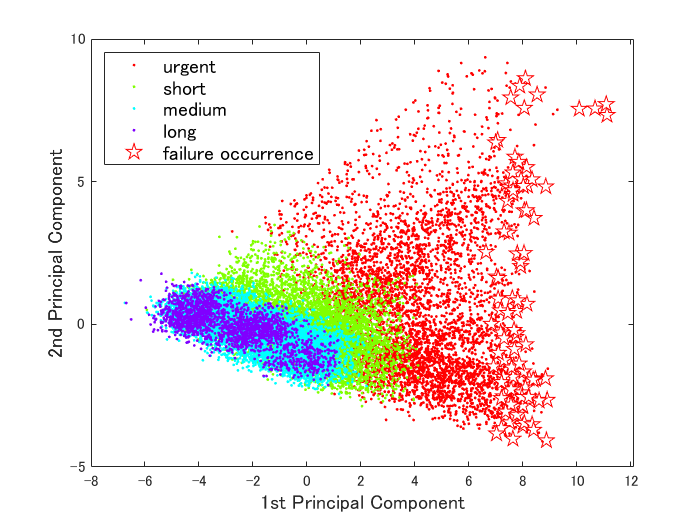


% Creating a plot of the first two components
figure
s1 = gscatter(score(:,1), score(:,2), dataTrainZ.Label);
hold on;
idx = dataTrainZ.Time == 0;
s2 = plot(score(idx,1), score(idx,2),'rp','MarkerSize',10,'MarkerFaceColor','w');
legend([s1; s2],{'urgent','short','medium','long','failure occurrence'},...
    'Color',    [1 1 1],...
    'Location', 'northwest',...
    'FontSize', 12);
xlabel('1st Principal Component','FontSize',12);
ylabel('2nd Principal Component','FontSize',12);

## 故障発生に至るまでの主成分平面上での軌道

試しに、個々のエンジンに対して、メンテナンス直後から障害発生までの間に主成分平面上でどのような軌道を辿るかを確認してみましょう。一例として、以下ではデータセットの1台目のエンジン (Unit-1) の軌道を可視化してみます。

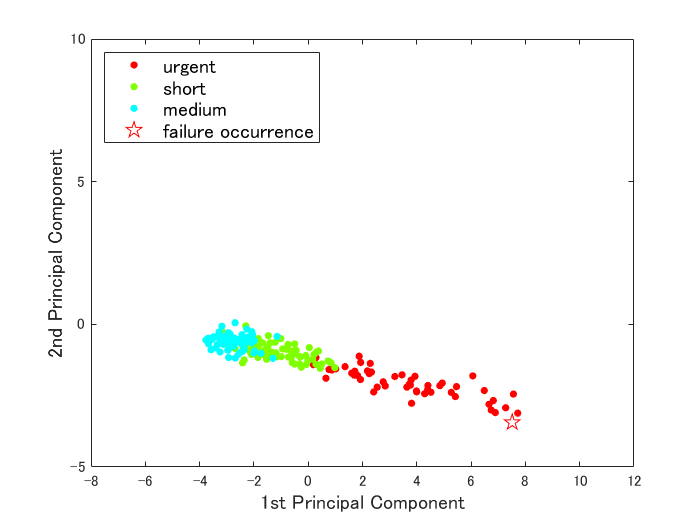

idxUnit = dataTrain.Unit == 1;
idxFailure = idxUnit & dataTrainZ.Time == 0;

figure
s1 = gscatter(score(idxUnit,1), score(idxUnit,2), dataTrainZ.Label(idxUnit));
hold on;
idx = dataTrainZ.Time == 0;
s2 = plot(score(idxFailure,1), score(idxFailure,2),'rp','MarkerSize',10,'MarkerFaceColor','w');
legend([s1; s2],{'urgent','short','medium','failure occurrence'},...
    'Color',    [1 1 1],...
    'Location', 'northwest',...
    'FontSize', 12);
xlabel('1st Principal Component','FontSize',12);
ylabel('2nd Principal Component','FontSize',12);
ax = gca;
ax.XLim = [-8 12];
ax.YLim = [-5 10];

## 前処理後のデータの保存

以降それぞれのデモで用いるため、前処理後のデータを .mat 形式で保存します。

save('Preprocessed_FD001.mat','dataTrainZ','dataTest','score','wcoeff','mu','sigma');

*Copyright 2020 The MathWorks, Inc.*